clear all
load('entradaSquare.mat')
load('salidaSquare.mat')

entradaEntrenamiento = entradaSquare(1:1500)

entradaEntrenamiento =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


salidaEntrenamiento = salidaSquare(1:1500)

salidaEntrenamiento =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


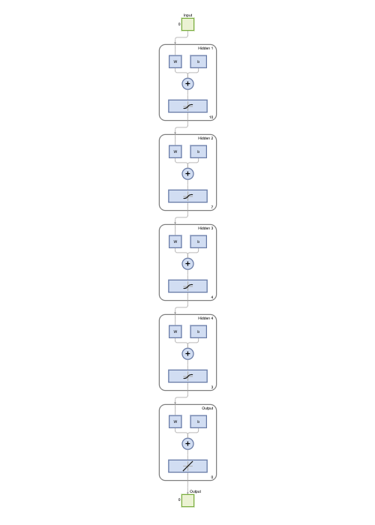


red = fitnet([10,7,4,3]);
view(red)

red.layers{1}.transferFcn='logsig'

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 134
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

red.layers{2}.transferFcn='logsig'

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 134
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

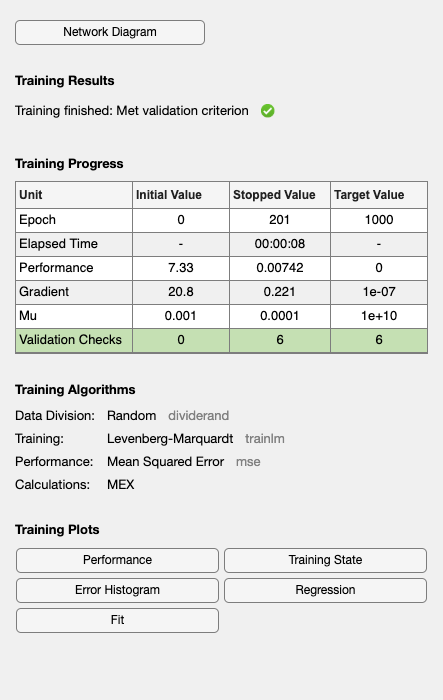

red =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 148
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [2 3 7 8 10 13 14 17 18 19 20 21 22 24 25 26 28 29 31 33 34 35 36 37 38 39 41 42 44 45 48 49 53 54 55 56 57 58 59 60 62 66 67 69 70 72 74 75 76 78 79 84 85 86 87 88 90 92 93 94 95 96 97 99 101 102 103 104 106 107 109 111 112 113 114 … ]
          valInd: [1 9 11 12 27 30 32 43 68 81 89 105 108 117 119 124 129 135 146 147 161 164 168 172 179 180 190 192 197 198 202 204 212 214 234 235 236 245 254 261 267 269 277 279 285 287 291 294 296 306 310 331 337 350 361 368 370 374 376 380 383 … ]
         testInd: [4 5 6 15 16 23 40 46 47 50 51 52 61 63 64 65 71 73 77 80 82 83 91 98 100 110 122 123 139 152 175 206 207 215 216 217 222 230 238 240 246 248 249 252 257 259 260 263 268 282 289 290 292 322 324 333 335 341 343 34

[red,tr] = train(red,entradaEntrenamiento.',salidaEntrenamiento.')